clear
clc
close all

dt = 0.00005;
t = 0:dt:100;

G = 1.183266613e-4;
m1 = 30000;
m2 = 30000*2;
m3 = 30000*1.5;

% r0 = [10*rand,10*rand,10*rand; %Posicion de m1 (en unidades astronomicas)
%     10*rand,10*rand,10*rand;  %Posicion de m2 (en unidades astronomicas)
%     10*rand,10*rand,10*rand] %Posicion de m3 (en unidades astronomicas)

r0 = [3.922270195341682,6.554778901775567,1.711866878115618; %Posicion de m1 (en unidades astronomicas)
    7.060460880196088,0.318328463774207,2.769229849608900;  %Posicion de m2 (en unidades astronomicas)
    0.461713906311539,0.971317812358475,8.234578283272926] %Posicion de m3 (en unidades astronomicas)

r0 =     3.9223    6.5548    1.7119
    7.0605    0.3183    2.7692
    0.4617    0.9713    8.2346


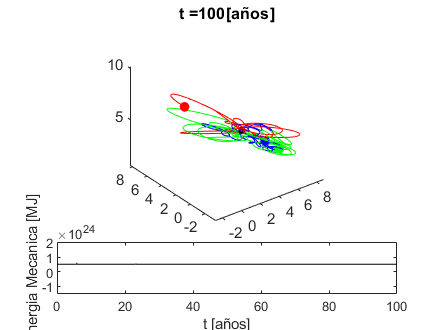


v0 = [0,0,0; %Velocidad de m1 (UA por año)
    0,0,0;  %Velocidad de m2 (UA por año)
    0,0,0]; %Velocidad de m3 (UA por año)

k12 = G * m1 * m2;
k23 = G * m2 * m3;
k13 = G * m1 * m3;

F12 = @(x1,x2,y1,y2,z1,z2) k12/( ...
    (x1-x2).^2+ ...
    (y1-y2).^2+ ...
    (z1-z2).^2).^(3/2);
    
F23 = @(x2,x3,y2,y3,z2,z3) k23/( ...
    (x2-x3).^2+ ...
    (y2-y3).^2+ ...
    (z2-z3).^2).^(3/2);
F13 = @(x1,x3,y1,y3,z1,z3) k13/( ...
    (x1-x3).^2+ ...
    (y1-y3).^2+ ...
    (z1-z3).^2).^(3/2);

r = r0;

v = v0;

M = [m1 m2 m3];

cm = (m1*r(1,:)+m2*r(2,:)+m3*r(3,:)) / sum(M);

X1 = zeros(1,length(t));
Y1 = zeros(1,length(t));
Z1 = zeros(1,length(t));

X2 = zeros(1,length(t));
Y2 = zeros(1,length(t));
Z2 = zeros(1,length(t));

X3 = zeros(1,length(t));
Y3 = zeros(1,length(t));
Z3 = zeros(1,length(t));

E = zeros(1,length(t));

for i = 1:1:length(t)

    f_12 = F12(r(1,1),r(2,1),r(1,2),r(2,2),r(1,3),r(2,3));
    f_13 = F13(r(1,1),r(3,1),r(1,2),r(3,2),r(1,3),r(3,3));
    f_23 = F23(r(2,1),r(3,1),r(2,2),r(3,2),r(2,3),r(3,3));

    a = -1*[(f_12 *(r(1,1)-r(2,1)) + f_13*(r(1,1)-r(3,1)))/m1,...
    (f_12*(r(1,2)-r(2,2)) + f_13*(r(1,2)-r(3,2)))/m1,...
    (f_12*(r(1,3)-r(2,3)) + f_13*(r(1,3)-r(3,3)))/m1;...
    (f_12*(r(2,1)-r(1,1)) + f_23*(r(2,1)-r(3,1)))/m2,...
    (f_12*(r(2,2)-r(1,2)) + f_23*(r(2,2)-r(3,2)))/m2,...
    (f_12*(r(2,3)-r(1,3)) + f_23*(r(2,3)-r(3,3)))/m2;...
    (f_13*(r(3,1)-r(1,1)) + f_23*(r(3,1)-r(2,1)))/m3,...
    (f_13*(r(3,2)-r(1,2)) + f_23*(r(3,2)-r(2,2)))/m3,...
    (f_13*(r(3,3)-r(1,3)) + f_23*(r(3,3)-r(2,3)))/m3];
    
    v_one_half = v + 1/2 * dt * a;

    r = r + dt * v_one_half;

    f_12 = F12(r(1,1),r(2,1),r(1,2),r(2,2),r(1,3),r(2,3));
    f_13 = F13(r(1,1),r(3,1),r(1,2),r(3,2),r(1,3),r(3,3));
    f_23 = F23(r(2,1),r(3,1),r(2,2),r(3,2),r(2,3),r(3,3));

    a = -1*[(f_12 *(r(1,1)-r(2,1)) + f_13*(r(1,1)-r(3,1)))/m1,...
    (f_12*(r(1,2)-r(2,2)) + f_13*(r(1,2)-r(3,2)))/m1,...
    (f_12*(r(1,3)-r(2,3)) + f_13*(r(1,3)-r(3,3)))/m1;...
    (f_12*(r(2,1)-r(1,1)) + f_23*(r(2,1)-r(3,1)))/m2,...
    (f_12*(r(2,2)-r(1,2)) + f_23*(r(2,2)-r(3,2)))/m2,...
    (f_12*(r(2,3)-r(1,3)) + f_23*(r(2,3)-r(3,3)))/m2;...
    (f_13*(r(3,1)-r(1,1)) + f_23*(r(3,1)-r(2,1)))/m3,...
    (f_13*(r(3,2)-r(1,2)) + f_23*(r(3,2)-r(2,2)))/m3,...
    (f_13*(r(3,3)-r(1,3)) + f_23*(r(3,3)-r(2,3)))/m3];

    v = v_one_half + 1/2 * dt * a;

    cm = (m1*r(1,:)+m2*r(2,:)+m3*r(3,:)) / sum(M);

    u = -1*k12/sqrt((r(2,1)-r(1,1)).^2+(r(2,2)-r(1,2)).^2+(r(2,3)-r(1,3)).^2) + ... 
        -1*k13/sqrt((r(1,1)-r(3,1)).^2+(r(1,2)-r(3,2)).^2+(r(1,3)-r(3,3)).^2) +... 
        -1*k23/sqrt((r(2,1)-r(3,1)).^2+(r(2,2)-r(3,2)).^2+(r(2,3)-r(3,3)).^2);

    k = 1/2 * m1 * norm(v(1,:))^2 +...
        1/2 * m2 * norm(v(2,:))^2 +...
        1/2 * m3 * norm(v(3,:))^2;

    Mec = abs((u + k)*5.9720e+18);

    X1(i) = r(1,1);
    Y1(i) = r(1,2);
    Z1(i) = r(1,3);

    X2(i) = r(2,1);
    Y2(i) = r(2,2);
    Z2(i) = r(2,3);

    X3(i) = r(3,1);
    Y3(i) = r(3,2);
    Z3(i) = r(3,3);

    E(i) = Mec; 
        
    if i == 1
        figure(1)
        subplot(4,3,[1,2,3,4,5,6,7,8,9])
        axis equal
        p1 = plot3(r(1,1),r(1,2),r(1,3),'.g', MarkerSize=20); hold on
        p2 = plot3(r(2,1),r(2,2),r(2,3),'.b', MarkerSize=20); hold on
        p3 = plot3(r(3,1),r(3,2),r(3,3),'.r', MarkerSize=20); hold on
        p4 = plot3(cm(1),cm(2),cm(3),'.k', MarkerSize=10); hold on

        l1 = plot3(X1(1:i),Y1(1:i),Z1(1:i),'g',LineWidth=0.5); hold on
        l2 = plot3(X2(1:i),Y2(1:i),Z2(1:i),'b',LineWidth=0.5); hold on
        l3 = plot3(X3(1:i),Y3(1:i),Z3(1:i),'r',LineWidth=0.5);  

        title(strcat('t = ', num2str(round(t(i),2)),'[años]'))
        
        subplot(4,3,[10,11,12])
        l4 = plot(t(1:i),E(1:i),'k');hold on
        xlabel('t [años]')
        ylabel('Energia Mecanica [MJ]')
        xlim([0,t(end)])
        ylim([-3*Mec 4*Mec])
        
        
       
    elseif mod(i,10000) == 0
        subplot(4,3,[1,2,3,4,5,6,7,8,9])
        set(p1,'XData',r(1,1),'YData',r(1,2),'ZData',r(1,3));
        set(p2,'XData',r(2,1),'YData',r(2,2),'ZData',r(2,3));
        set(p3,'XData',r(3,1),'YData',r(3,2),'ZData',r(3,3));
        set(p4,'XData',cm(1),'YData',cm(2),'ZData',cm(3));

        set(l1,'XData',X1(1:i),'YData',Y1(1:i),'ZData',Z1(1:i));
        set(l2,'XData',X2(1:i),'YData',Y2(1:i),'ZData',Z2(1:i));
        set(l3,'XData',X3(1:i),'YData',Y3(1:i),'ZData',Z3(1:i));
        axis equal
        title(strcat('t = ', num2str(round(t(i),2)),'[años]'))
        
        subplot(4,3,[10,11,12])
        set(l4,'XData',t(1:i),'YData',E(1:i));

        pause(0.001)
    end

end